## Pulizia

clear

## Caricamento dati

root = "C:\Users\trima\OneDrive - unime.it\Appunti Università\Appunti condivisi\00) Tirocinio\Trimarchi\V2G-with-Regression-Learner-and-LSTM-NN";
% Aggiungiamo il percorso degli script
addpath(root + "\Scripts");
%zone_id=1; %"Zone_509_Ponte Mammolo";
%zone_id=2; %"Zone_116_Trastevere";
%fzone_id=3; %"Zone_125";
%zone_id=4; %"Zone_705_Prenestino-Centocelle";;
%zone_id=5; %"Eur 1201"
%zone_id=6;
%zone_id=7; %"Zone_906_Arco_Di_Travertino"
%zone_id=8; % Zona 1016
zone_id=9; %Zona 214 Trieste
%zone_id=10; % Zona 2004
%zone_id=11; % Zona 2002
%zone_id=12; %Torvergata

% Usiamo uno script che vuole come parametro la root e la zona da caricare
datas = load_datas(root,zone_id);

Dati per la zona "Zone_214_Trieste" caricati correttamente.


## Costanti

num_lags = 48;
predittori = {'AAC_energy','precipprob','temp','windspeed', 'holiday_indicator'};
target = 'AAC_energy';
colonne_da_normalizzare = [predittori, target];

giorniValidation = [
    datetime(2023,2,21) % regressore
    datetime(2023,2,22) % giorno test
    datetime(2023,7,21) % regressore
    datetime(2023,7,22) % giorno test
];

giorniTest = [
    datetime(2023,6,7) % regressore
    datetime(2023,6,8) % giorno test
    datetime(2023,10,7) % regressore
    datetime(2023,10,8) % giorno test
];

## Sistemazione dati

%datas = timevector_hour_to_number(data);
%datas = timevector_to_number(datas);
%datas = is_zero(datas);
[training, validation, test] = get_training_test_validation(datas, giorniValidation, giorniTest);

Create tabelle Training, Validation e Test per LSTM NN


[training_norm, test_norm, params_norm] = normalize_zscore(training, test, colonne_da_normalizzare);

Normalizzate tabelle con metodo z-score


[training_norm, validation_norm, params_norm] = normalize_zscore(training, validation, colonne_da_normalizzare);

Normalizzate tabelle con metodo z-score


[Xtraining, Ytraining, time_vector_training] = create_lags_LSTMNN(training_norm, num_lags, predittori, target);

Giorni totali: 50
Giorni consecutivi validi: 42
Lunghezza sequenza (num_predittori): 48
Numero di feature: 5
Numero di target: 1
Numero di sequenze create: 2016
Modalità 1-step ahead: target spostato di 1 campione/i.
Creazione sequenze LSTM completata


[Xtest, Ytest, time_vector_test] = create_lags_LSTMNN(test_norm, num_lags, predittori, target);

Giorni totali: 4
Giorni consecutivi validi: 2
Lunghezza sequenza (num_predittori): 48
Numero di feature: 5
Numero di target: 1
Numero di sequenze create: 96
Modalità 1-step ahead: target spostato di 1 campione/i.
Creazione sequenze LSTM completata


[Xvalidation, Yvalidation, time_vector_validation] = create_lags_LSTMNN(validation_norm, num_lags, predittori, target);

Giorni totali: 4
Giorni consecutivi validi: 2
Lunghezza sequenza (num_predittori): 48
Numero di feature: 5
Numero di target: 1
Numero di sequenze create: 96
Modalità 1-step ahead: target spostato di 1 campione/i.
Creazione sequenze LSTM completata


## Modello Long Short Term Memory NN

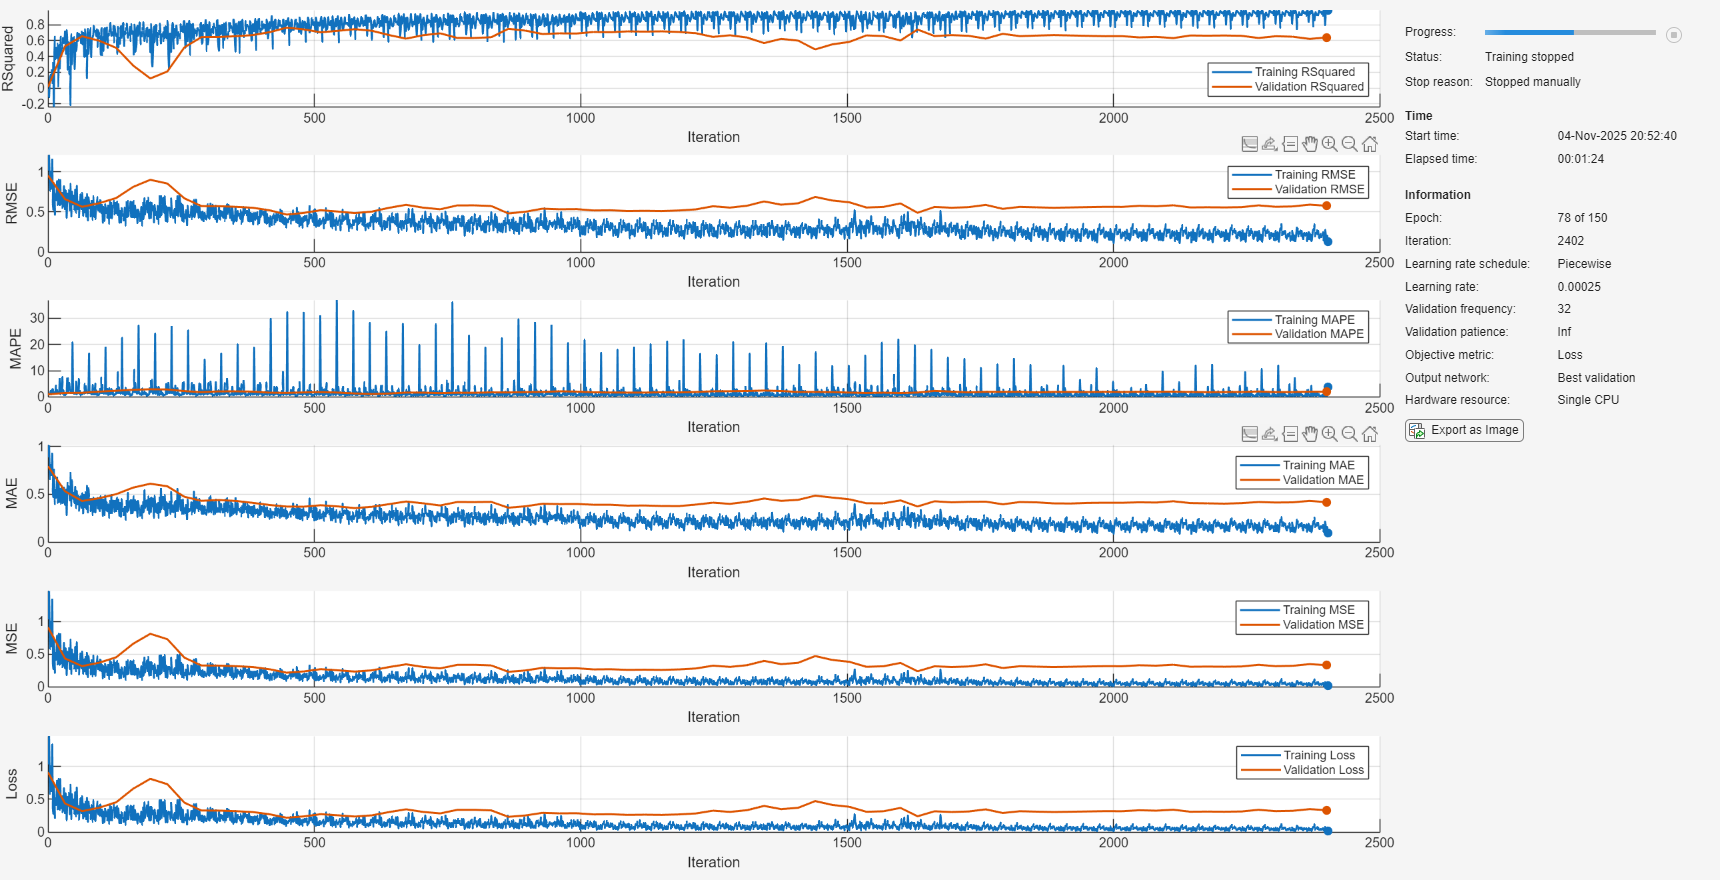

numFeatures = size(Xtraining{1}, 2);      
numResponses = size(Ytraining, 2);                     

numHiddenUnits = 128;                                   % Unità LSTM per catturare dipendenze temporali
drop = 0.2;                                             % Dropout per regolarizzazione
mb = 64;                                                % Mini-batch più moderato per stabilità
valFreq = max(1, ceil(numel(Xtraining) / mb));          % Frequenza validazione legata al numero di batch


% LSTM classico (unidirezionale) processa solo dal passato 
% verso il presente, quindi vede solo ciò che è già accaduto.
layers = [
    sequenceInputLayer(numFeatures, Normalization="none")        % Dati già normalizzati a monte (z-score)
    lstmLayer(numHiddenUnits, OutputMode="sequence")                 % Output ultimo timestep (seq2one)
    dropoutLayer(drop)                                           % Regolarizzazione
    lstmLayer(numHiddenUnits/2, OutputMode="sequence")
    dropoutLayer(drop)
    lstmLayer(numHiddenUnits/4, OutputMode="last")
    fullyConnectedLayer(numResponses)                            % Mappa al numero di target
];

% Opzioni di training (trainnet)
options = trainingOptions("adam", ...
    MaxEpochs=150, ...
    MiniBatchSize=mb, ...
    Shuffle="never", ...                                  % Gabriele ha messo none
    InitialLearnRate=1e-3, ...
    LearnRateSchedule="piecewise", ...
    LearnRateDropFactor=0.5, ...
    LearnRateDropPeriod=30, ...
    GradientThreshold=1, ...
    GradientThresholdMethod="l2norm", ...
    L2Regularization=1e-4, ...
    ValidationData={Xvalidation, Yvalidation}, ...
    ValidationFrequency=valFreq, ...
    Metrics=["rsquared","rmse","mape","mae","mse"], ... 
    Plots="training-progress", ...
    Verbose=false, ...
    ExecutionEnvironment="auto" ...
);

% Addestramento 
[net, info] = trainnet(Xtraining, Ytraining, layers, "mse", options);  

% Salvataggio dati

ts = datestr(now, 'yyyy_mm_dd_HH_MM_SS');    
NET_NAME = ['net_' ts];                                   

indicators = get_best_indicators(info); 

net_struct = struct();                                             
net_struct.zone_id = zone_id;                                      
net_struct.net = net;         
net_struct.net_indicators = indicators;                             
net_struct.layers = layers;                                         
net_struct.options = options;                                       
net_struct.numFeatures = numFeatures;                               
net_struct.numResponses = numResponses;                            
net_struct.numHiddenUnits = numHiddenUnits;                         

net_struct.Xtraining = Xtraining;                                   
net_struct.Ytraining = Ytraining;                                  
net_struct.time_vector_training = time_vector_training;
net_struct.Xtest = Xtest;                                          
net_struct.Ytest = Ytest;                                          
net_struct.time_vector_test = time_vector_test;
net_struct.Xvalidation = Xvalidation;                               
net_struct.Yvalidation = Yvalidation;                              
net_struct.time_vector_validation = time_vector_validation;

net_struct.training_data = training;                                
net_struct.test_data = test;                                       
net_struct.validation_data = validation;                            
net_struct.training_data_norm = training_norm;                      
net_struct.test_data_norm = test_norm;                             
net_struct.validation_data_norm = validation_norm;                 
net_struct.parametri_norm = params_norm;                            

models = struct();                                        
models.(NET_NAME) = net_struct;                                     

save_models(root, models, NET_NAME, net);  % Accoda/salva nel file giornaliero Models_YYYY_mm_dd.mat nella cartella sessioni 

Modello "net_2025_11_04_20_54_07" salvato in: C:\Users\trima\OneDrive - unime.it\Appunti Università\Appunti condivisi\00) Tirocinio\Trimarchi\V2G-with-Regression-Learner-and-LSTM-NN\sessioni\2025_11_04\Models_2025_11_04.mat


## Grafico LSTM NN

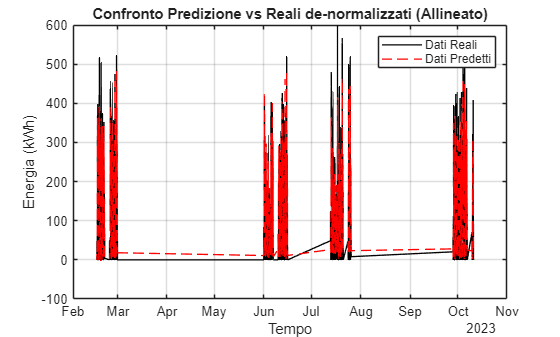

training_fig =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


predizione_training = minibatchpredict(models.(NET_NAME).net, models.(NET_NAME).Xtraining);
training_fig = get_plot(predizione_training, models.(NET_NAME).Ytraining, models.(NET_NAME).parametri_norm, target, models.(NET_NAME).time_vector_training)

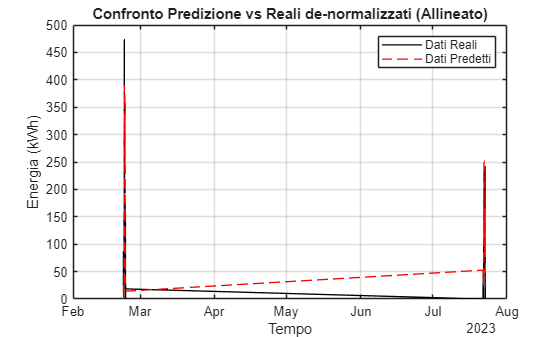

validation_fig =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


predizione_validation = minibatchpredict(models.(NET_NAME).net, models.(NET_NAME).Xvalidation);
validation_fig = get_plot(predizione_validation, models.(NET_NAME).Yvalidation, models.(NET_NAME).parametri_norm, target, models.(NET_NAME).time_vector_validation)

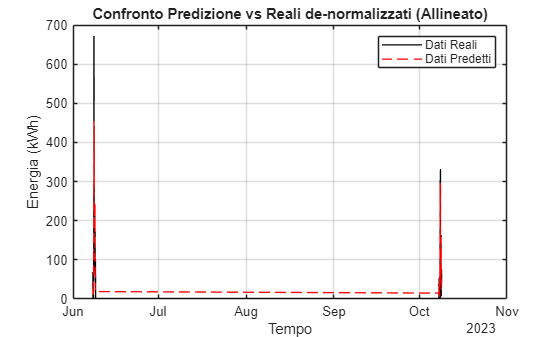

test_fig =   Figure (7) with properties:

      Number: 7
        Name: ''
       Color: [1 1 1]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


predizione_test = minibatchpredict(models.(NET_NAME).net, models.(NET_NAME).Xtest);
test_fig = get_plot(predizione_test, models.(NET_NAME).Ytest, models.(NET_NAME).parametri_norm, target, models.(NET_NAME).time_vector_test)

models.(NET_NAME).net_indicators.Test = get_indicators(predizione_test, Ytest);
save_models(root, models, NET_NAME, net);

Modello "net_2025_11_04_20_54_07" salvato in: C:\Users\trima\OneDrive - unime.it\Appunti Università\Appunti condivisi\00) Tirocinio\Trimarchi\V2G-with-Regression-Learner-and-LSTM-NN\sessioni\2025_11_04\Models_2025_11_04.mat


currentDate = datestr(now, 'yyyy_mm_dd');                      
matFile = fullfile(root, 'Sessioni', currentDate, ['Models_' currentDate '.mat']);            
load(matFile);